# Contest Report

% Read in the list of all solvers
solvers = readtimetable("allSolvers.csv");

% Get rid of bad entries
% The result may be infinite or negative. Neither is a good state.
ix = isinf(solvers.result)|(solvers.result<0);
solvers(ix,:) = [];

Here is the list of all the solvers

solvers

solvers = 4x5 timetable
             t              result    computeTime    score       author                         commit                   
    ____________________    ______    ___________    ______    __________    ____________________________________________

    06-May-2024 21:52:36    26.017      0.34412       164.5    {'gulley'}    {'c51b2fcf7b51ebe382d55723d14c15474980b116'}
    06-May-2024 21:58:25    8447.5     0.010434       42238    {'gulley'}    {'0b53da950386771ea06a279705761aca016bc1c5'}
    06-May-2024 22:20:06    103.18      0.25395      541.27    {'gulley'}    {'678373370c5a44c8ded9859054450b2296fd572f'}
    06-May-2024 22:27:42    26.017      0.31405      161.49    {'gulley'}    {'7f9f69f3d432c009b2b02cfaaa6240e5bc91370b'}


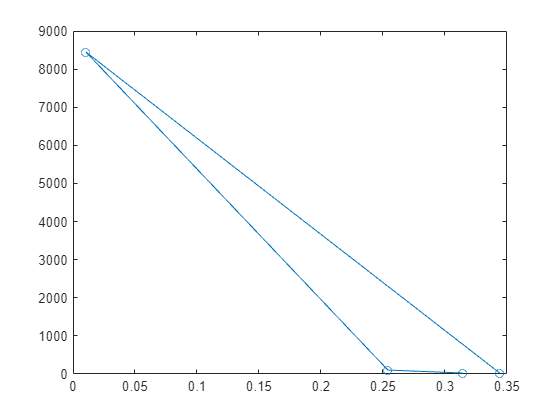

plot(solvers.computeTime,solvers.result,"-o")

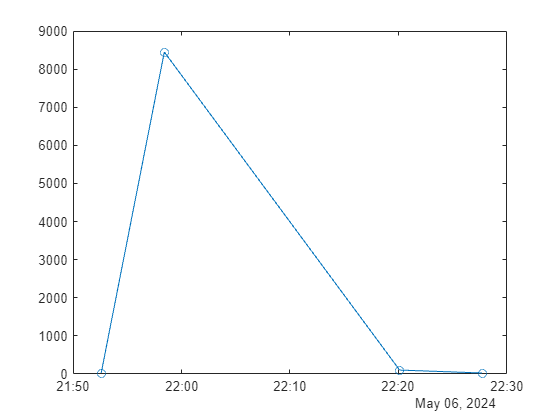

plot(solvers.t,solvers.result,"-o")

Calculate leaders

bestScore = inf;
ixLeader = zeros(height(t),1);

Unrecognized function or variable 't'.

for i = 1:height(solvers)
    if solvers.score(i) < bestScore
        ixLeader(i) = 1;
        bestScore = solvers.score(i);
    end
end

leaders = solvers(ixLeader,:)

